## Further Classification Techniques (10/03/2021)

Week 5 of the Intro to Data Science module looks at further classification methods. Last week, we looked at Decision Trees and the confusion matrix, as well as how to use this to extract meaningful model performance metrics, which was observed with application to the Titanic dataset. This week, we extend our understanding of classifiers by considering the support vector machine (SVM) linear classifier, discriminant analysis classification, and the k-Nearest Neighbour classifier. We start with some theory, followed by a practical application on the titanic dataset.

### Further Classification Theory

In the broadest sense, a **linear classifier** attempts to separate a dataset into a set of (2) classes. We can consider the data as a set of points in the input or embedding space, which if linearly separably, should be capable of being split into two subsets using a straight partition, which is facilitated by a "hyperplane". In essence, the hyperplane encompasses the set of points for which the dot product of the weights and input vector (plus a bias) is equal to 0, hence being either positive or negative and falling into the respective class if present in either half-space. This hyperplane is positioned to match our requirements, e.g. for the greatest distance between points and the plane, or for greatest separability - different techniques exist for these different criteria.

The **Support Vector Machine (SVM)** finds the hyperplane that maximises the distance from the nearest point, hence maximising the "margin". The linear SVM is arguably the simplest linear classifier, while the so-called "kernel trick" can be used to to map a more complex input function into an easier domain, which can be solved using a simple SVM.

**Discriminant Analysis Classifiers** work in a similar way to the statistical testing which was previously covered. It assumes that the different classes present in the data are driven by different Gaussian distributions, and so the process aims to separate these by optimising a cost function which relates to the difference in means (squared) divided by the sum of variances.

**k-Nearest Neighbours** is a non-parametric algorithm (doesn't assume data distribution or structure), and inherently supports multiple classes due to the way it works (similar to a decision tree). For each point in the dataset, the closest k points are found, and the class of the individual is selected as the majority vote of these surrounding points. K should ideally be odd to avoid equal votes, and it is important to be able to specifying some notion of distance, and to select a meaningful value of k, with a larger k being more general, and a smaller k being more specific and highly fit.

### Practical Application of Classifiers

As mentioned above, we will explore the Titanic dataset once more. We begin by importing our data, and visualising a sample.

data = readtable("./data/titanic.csv");

head(data,5)

ans = 5×8 table
    Survived    Pclass                             Name                                Sex        Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    ______________________________________________________    __________    ___    ______________________    ______________________    ______

       0          3       {'Mr. Owen Harris Braund'                            }    {'male'  }    22               1                         0                 7.25
       1          1       {'Mrs. John Bradley (Florence Briggs Thayer) Cumings'}    {'female'}    38               1                         0               71.283
       1          3       {'Miss. Laina Heikkinen'     

We then preprocess and reformat our data. This will include dropping unnecessary columns (e.g. Name), encoding our categoric variables in numeric form (e.g. Sex), and splitting our dataset into a vector of features and labels.

% Drop irrelevant information - name
data.Name = [];

% Encode categorical data to numeric form - sex
data.Sex = grp2idx(data.Sex);

% Split data into labels and features
labels = data.Survived;
features = data(:,2:end);

In order to assess the performance of our classifiers, we want to form a training and testing subset from these labels and feature vectors. We can do this using random numbers.

% Create a vector of random numbers for splitting dataset
r = rand(length(labels),1);

% Assign indices to either data split depending on number
train = find(r < 0.7);
test = find(r >= 0.7);

% Assign the data points (labels, features) to corresponding split
train_labels = labels(train);
test_labels = labels(test);
train_features = features(train, :);
test_features = features(test, :);

We can now train our classifiers. We will do this for each type in turn (SVM, Discriminant Analysis, KNN) and evaluate their relative effectiveness.

% Linear SVM
svm = fitclinear(train_features, train_labels,'Learner','svm');
predictions = predict(svm, test_features);
c = confusionmat(predictions, test_labels);
TP = c(1); FN = c(2); FP = c(3); TN = c(4);
accuracy_svm = (TP + TN) / (TP + TN + FP + FN);
recall_svm = TP / (TP + FN);
precision_svm = TP / (TP + FP);
specificity_svm = TN / (TN + FP);

% Linear Discriminant Analysis 
discriminant = fitcdiscr(train_features, train_labels);
predictions = predict(discriminant, test_features);
c = confusionmat(predictions, test_labels);
TP = c(1); FN = c(2); FP = c(3); TN = c(4);
accuracy_lda = (TP + TN) / (TP + TN + FP + FN);
recall_lda = TP / (TP + FN);
precision_lda = TP / (TP + FP);
specificity_lda = TN / (TN + FP);

% K Nearest Neighbours
knn = fitcknn(train_features, train_labels, 'NumNeighbors',3);
predictions = predict(knn, test_features);
c = confusionmat(test_labels, predictions);
TP = c(1); FN = c(2); FP = c(3); TN = c(4);
accuracy_knn = (TP + TN) / (TP + TN + FP + FN);
recall_knn = TP / (TP + FN);
precision_knn = TP / (TP + FP);
specificity_knn = TN / (TN + FP);

% Tabulate the performance metrics
T = table([accuracy_svm, accuracy_lda, accuracy_knn]', ...
          [recall_svm, recall_lda, recall_knn]', ...
          [precision_svm, precision_lda, precision_knn]', ...
          [specificity_svm, specificity_lda, specificity_knn]');

T.Properties.VariableNames = ["Accuracy", "Recall", "Precision", "Specificity"];
T.Properties.RowNames = ["SVM", "LDA", "KNN"]

T = 3×4 table
           Accuracy    Recall     Precision    Specificity
           ________    _______    _________    ___________

    SVM    0.79435     0.83448     0.81757       0.73786  
    LDA    0.79435     0.82759     0.82192       0.74757  
    KNN    0.67339     0.70513     0.75862       0.61957  


LDA appeared to perform best at this classification exercise, scoring the highest across all the metrics. This illustrates that it may be a decent assumption to model the different classes as gaussian distributions, being the underlying assumption for the LDA approach. The SVM performs slightly worse, but still achieves a 76% accuracy, showing that linear separability is a decent assumption, even if not optimal. The KNN performed considerably poorer in this example, however, this may be a biproduct of the selection of k-value, which is in need of further investigation.

It is worth recalling the performance observed by the decision tree last week, achieving a classification accuracy of 81%, which outperforms all the linear classifiers examined this week using a 70% training split. This suggests the potential presence of a non-linear relationship between the feature vectors and label, which is better captured by the decision tree than a linear classifier.

For completeness, we will now investigate further the sensitivity for the different classifiers with respect to different amounts of training data, and in the case of the KNN classifier, different choices of k-value. We start with the KNN investigation.

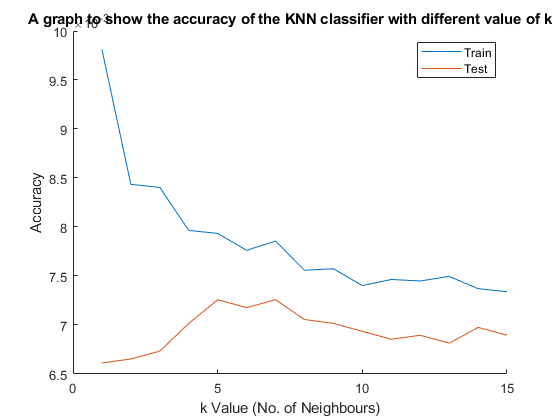

MAX_K = 15;
accuracies_train = zeros(MAX_K,1);
accuracies_test = zeros(MAX_K,1);

for k = 1:MAX_K
 
 accuracies_train_temp = zeros(100,1);
 accuracies_test_temp = zeros(100,1);
 
 % Average over 100 runs
 for test_num = 1:1
     % Fit the knn classifier with k neighbours (incremented)
     t = fitcknn(train_features, train_labels, 'NumNeighbors',k);
     
     % Evaluate on training set
     predictions_train = predict(t, train_features);
     c_train = confusionmat(train_labels, predictions_train);
     accuracy_train = sum(diag(c_train))/sum(sum(c_train));
     accuracies_train_temp(test_num) = accuracy_train;
     
     % Evaluate on testing set
     predictions_test = predict(t, test_features);
     c_test = confusionmat(test_labels, predictions_test);
     accuracy_test = sum(diag(c_test))/sum(sum(c_test));
     accuracies_test_temp(test_num) = accuracy_test;
 end
 
 accuracies_train(k) = mean(accuracies_train_temp);
 accuracies_test(k) = mean(accuracies_test_temp);
 
end

% Plot the graph to compare
figure;
hold on;
plot(accuracies_train, "DisplayName", "Train");
plot(accuracies_test, "DisplayName", "Test");
legend();
hold off;
xlabel("k Value (No. of Neighbours)");
ylabel("Accuracy");
title("A graph to show the accuracy of the KNN classifier with different value of k")

As can be from the chart above, the training accuracy of the KNN classifier decreases with an increasing value of k. This is because the value of k refers to how many neighbours are used to compute the target class, essentially emulating a high order polynomial fit, which is likely to overfit and cause poor generalisability, as viewed from the poor test performance. Increasing the value of k thereby decreases the training performance, however contributing to a greater test accuracy due to improved generalisability. A greater value of k produces smoother decision boundaries, similar to a lower order polynomial which is preferred if it contains enough spatial resolution. This can be observed from the graph once more, with a k-value of 5 providing the best accuracy, and appearing to drop off after this, which is characteristic of underfitting.

We will now consider the impact of dataset size on training performance for our new detectors.

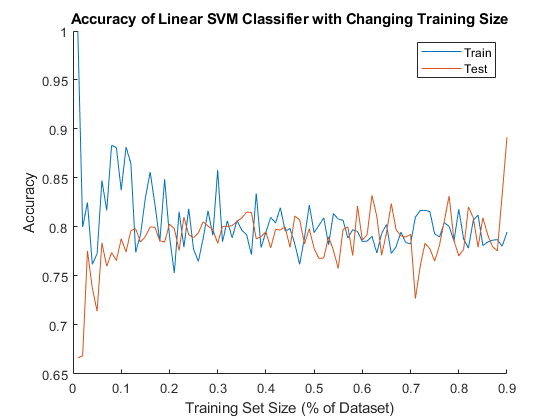

% Create arrays for storing the data
accuracies_train = zeros(90, 3); 
accuracies_test = zeros(90, 3);
x_data = 0.01:0.01:0.9;

for k = 0.01:0.01:0.9
 
 % Create splits of data
 r = rand(length(labels),1);
 train = find(r < k); test = find(r >= k);
 train_labels = labels(train); test_labels = labels(test);
 train_features = features(train, :); test_features = features(test, :);
 
 average_run_count = 10;
 accuracies_train_temp = zeros(average_run_count,3);
 accuracies_test_temp = zeros(average_run_count,3);
 
 for classifier_idx = 1:3
 
     % Fit classifier
     switch classifier_idx
         case 1
             classifier = fitclinear(train_features, train_labels, 'Learner','svm');
         case 2
             classifier = fitcdiscr(train_features, train_labels);
         case 3
             classifier = fitcknn(train_features, train_labels, 'NumNeighbors',5);
     end
     
     % Conduct repeat runs for an averaged value
     for test_num = 1:average_run_count

         % Evaluate on training set
         predictions_train = predict(classifier, train_features);
         c_train = confusionmat(train_labels, predictions_train);
         accuracy_train_val = sum(diag(c_train))/sum(sum(c_train));
         accuracies_train_temp(test_num, classifier_idx) = accuracy_train_val;
         
         % Evaluate on testing set
         predictions_test = predict(classifier, test_features);
         c_test = confusionmat(test_labels, predictions_test);
         accuracy_test_val = sum(diag(c_test))/sum(sum(c_test));
         accuracies_test_temp(test_num, classifier_idx) = accuracy_test_val;
        
     end
     
     % Average the values, and store in matrix
     accuracies_train(round(k*100), :) = mean(accuracies_train_temp);
     accuracies_test(round(k*100), :) = mean(accuracies_test_temp);
     
 end
end

% Plot the learning curve for the linear SVM
figure;
hold on;
plot(x_data, accuracies_train(:,1), "DisplayName", "Train");
plot(x_data, accuracies_test(:,1), "DisplayName", "Test");
legend(); hold off;
xlabel("Training Set Size (% of Dataset)");
ylabel("Accuracy");
title("Accuracy of Linear SVM Classifier with Changing Training Size")

The learning curve shows that by increasing the training samples, the training accuracy decreases and the test accuracy increases. This is what would be expected, with the far right of the graph showing a rough convergence between the training and test set with a decent accuracy of just under 80%, which indicates a good fit to the data. If the two curves were far apart, with an increasing training accuracy and decreasing test accuracy, then this would illustrate overfitting (high variance), while two converged curves with a low accuracy would illustrate underfitting (high bias).

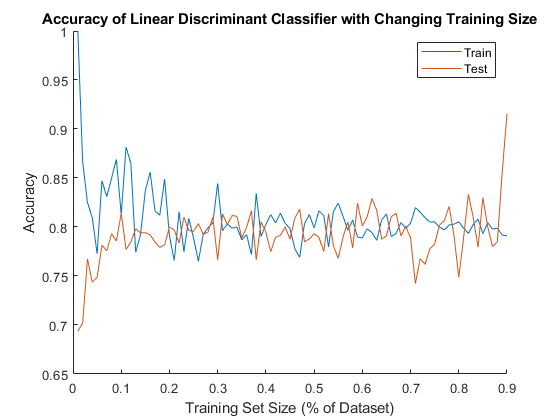

% Plot the learning curve for the Linear Discriminant Classifier
figure;
hold on;
plot(x_data, accuracies_train(:,2), "DisplayName", "Train");
plot(x_data, accuracies_test(:,2), "DisplayName", "Test");
legend(); hold off;
xlabel("Training Set Size (% of Dataset)");
ylabel("Accuracy");
title("Accuracy of Linear Discriminant Classifier with Changing Training Size")

The learning curve for LDA appears to highly resemble that of the SVM, with a similar convergence to an acceptable accuracy of 80%, illustrating a good fit with increasing amounts of data.

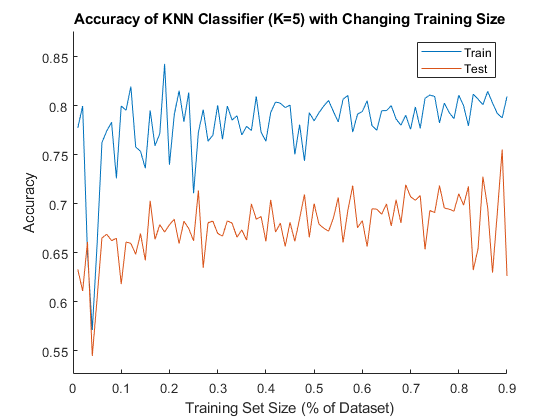

% Plot the Learning curve for the kNN Classifier
figure;
hold on;
plot(x_data, accuracies_train(:,3), "DisplayName", "Train");
plot(x_data, accuracies_test(:,3), "DisplayName", "Test");
legend(); hold off;
xlabel("Training Set Size (% of Dataset)");
ylabel("Accuracy");
title("Accuracy of KNN Classifier (K=5) with Changing Training Size")

The KNN's learning curve shows a different pattern to the other classifiers investigated, with an increasing training set corresponding to an increase in both the train and test accuracy. The training accuracy continues to increase as the KNN algorithm remembers these points as future classification reference points, while the test accuracy does not continue to increase, with a subtle decrease in accuracy observed at a large training set size, and with increased variance or magnitude of oscillations, highlighting potential overfitting. The maximum test accuracy obtained was around 70%.